# Spectrum Feature Quick Viewer + Table Maker （スピナー振動データ専用rD版）

- 2020/08/12 PHMC2020用に修正

- 2020/09/11 FOXCON用に修正 (注:SKとPS部分は未完)

- 2021/03/01 スピナー寿命確認用に修正

- input : rD (またはxTableをrDにrenameしたもの)

- output: TFS (feature table)

振動データを各変数に持つ、xTable, rD使用バージョン

- xTableは、P01_VibrationCSV2MAT.mlx によって測定CSVデータから時系列テーブル化されていること。

- 本スクリプトは、rDをベースに計算するので、rDがない場合は、XTableから名前を変えて作成しておくこと。rDは計算用のワークテーブルを意味する。rD = xTable として問題ない。

- rD中のどの変数を表示するか、設定すること。

- rDの構造は、例えば以下の通り

- 127393x1 timetable	127393x1 timetable	127393x1 timetable	127393x1 timetable	127393x1 timetable

- 217289x1 timetable	217289x1 timetable	217289x1 timetable	217289x1 timetable	217289x1 timetable

- 218382x1 timetable	218382x1 timetable	218382x1 timetable	218382x1 timetable	218382x1 timetable

- ：

注：各フィールドは先頭が、時刻相当、他振動データとみなして２列目から計算しているので、それ以外のデータを入れている場合は、前もって削除しておくこと。

    {'xDate'}    {'SN'}    {'Ax'}    {'Az'}    {'Ay'}    {'CT'}　など、XDate以外に***SN***などを入れている場合

振動データから特徴量を確認するスクリプト。ここですべての特徴量を計算しながら、MATファイルとは別に特徴量テーブルを作成する。XYZ軸など、複数の振動データがある場合は、各々に対して特徴量を計算する必要があるため、単一特徴量としてMATファイルに保存するのは得策ではない。

大量のデータを表示するとメモリ圧迫する可能性高いので、表示するかどうか設定する

#### バグFIX

- 2020/10/02 FFTで表示周波数を設定する場合のインデックスを整数にする関数にuint32からroundを使用する

## 変数設定

データのサンプリング周波数などは特定して、指定しておくこと

% rD = table2timetable(rD)
% % clear
fs = 50000         % Sampling frequency

fs = 50000

T = 1/fs           % Sampling period

T = 2.0000e-05

L = numel(rD(1,"vibration").vibration{1})   % Length of signal 100000

L = 100000

%t = (0:L-1) * T;
colors = parula(50);

prompt = {'Run Mode FFT/SK/PS/RAW:','Bushing number 2-5:', 'Max frequency 50000:', 'Time SP_TIME/xTime:' };
dlgtitle = 'Input';
dims = [1 1 1 1];
definput = {'FFT','2','200','SP_TIME'};
answer = inputdlg(prompt,dlgtitle,dims,definput);
if numel(answer) == 0
    return
end
runmode = answer{1}

runmode = 'FFT'

bs = str2num(answer{2})

bs = 5

timeaxis = answer{4}                        % scatter3(f, thour*ones(size(f)), P1, [], P1,".");

timeaxis = 'xTime'


fst = round(fs/str2double(answer{3}))       % 100;   % Target fs (Hz) range on plot　描画用周波数レンジ

fst = 20

wc = 128                                    % 128 でスペクトル尖度を計算するウィンドウサイズ

wc = 128

fsk = round(wc*8*str2double(answer{3})/fs)  % SKの表示用周波数範囲

fsk = 51

day = 1;                                    % 日時で変化するデータに使用
%TSK = table;                               % SK用のデータ保存テーブル

if exist("rD","var") == false
    load ("TrD.mat","rD");  %rD = running data table
end
Maxct = numel(rD{:,1});                     % 分析の最大行数設定(データ数)
Maxfld = numel(rD.Properties.VariableNames) % 分析の最大列数（分析変数の数）設定、XYZ軸方向など振動変数が複数ある場合に使用する

Maxfld = 5

                                            % rD変数の数だけ回す、ただし、1行目はSNなどに使用される前提で2から

## データの読込と計算処理

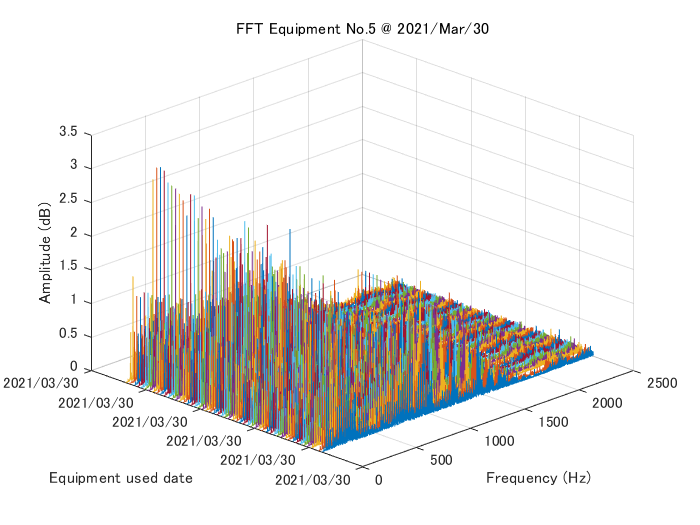

for ct = 1:Maxct       %行数、データ数
    if and(rD{ct,"BushingNo"} == bs, rD{ct,"STEP"} ==11) %, rD{ct,"HOLE"} == 41940)         
        gsdata = rD(ct,"vibration");         %. gsdata = rD(ct,'Value')
        gs = rD(ct,"vibration").vibration{1};    %. gs = gsdata.Value{1}
        g = rD(ct,"vibration").vibration{1}.Value;
%データ読み込みの変数指定方法参考
%        gs = rD(ct,ctfld).(1){1};    %. gs = gsdata.Value{1}
%        g = rD(ct,ctfld).(1){1}.(1);    % for で回せるように変数名ではなく、添字で指定、↑の記載と同じ意味
%        thour = rD(ct,"xDate").xDate;         % Y軸
%        L = numel(g)                   % Length of signal 100000、測定長さが異なる場合の備え

        switch timeaxis
            case "SP_TIME"
                thour = rD{ct,"SP_TIME"};           % Y軸スピナー時間
                % thour = rD(ct,1).(1);             % Y軸
            case "xTime"
                thour = datenum (rD{ct,"xTime"});
        end
        
        switch runmode
            case "RAW"
                ls = 100;              % 表示間隔 
                ysn = ct*ones(size(gs.Time));
                p=plot3(gs.Time(1:ls:end), ysn(1:ls:end), g(1:ls:end));
            %    scatter3(gs.Time(1:ls:end), ysn(1:ls:end), g(1:ls:end), [], g(1:ls:end),".");
%代用可    scatter3(gs.Time(1:ls:end), ysn(1:ls:end), gs.Fx(1:ls:end), [], gs.Fx(1:ls:end),".");

            case "PS"
                %[p1,f] = pspectrum(gs,'FrequencyResolution',25);
                [P1,f] = pspectrum(gs,'FrequencyLimits',[1 fs/fst],'FrequencyResolution',25);
%                p=plot3(f, thour*ones(size(f)), pow2db(P1));        %plot(f,pow2db(pdata))
                scatter3(f, thour*ones(size(f)), pow2db(P1), [], pow2db(P1),".");
                %rD(ct,{'freq';'power'}) = {f,P1};
                % writeToLastMemberRead(fensemble,'freq',fpdata,'spectrum',pdata);

                [P1Max,fI] = max(P1(2:end-1));  % 最大値とインデックス検索
                fmax = f(fI);                   % 最大の時の周波数
                TFS{ct,ctfld-1} = P1Max;        % 同時に計算することはないので変数とテーブルを共有
                
            case "SK" % スペクトル尖度プロット
                % 振動信号を取得%        v = data.vibration{1};
                [SK, f] = pkurtosis(g, fs, wc);
%                rD(ct,'SpectralKurtosis') = {table(f, SK)};    % rDに書き込む場合 %{f,P1}; %{f,P1};
                %rD.SpectralKurtosis = {table(f, SK)};
                p = plot3(f, thour*ones(size(f)), SK, 'Color', colors(mod(day,50)+1, :));
%                scatter3(f, thour*ones(size(f)), P1, [], P1,".");
              
                
%                 f=f(1:fsk);
%                 SK=SK(1:fsk);
%                 % スペクトル尖度をデータストアに書き込み
%                 % data2add = table;
%                 % data2add.SpectralKurtosis = {table(F, SK)};
%                 % writeToLastMemberRead(hsbearing, data2add);
%                 day = day + 1;    
% 
%                 [P1Max,fI] = max(SK(2:end-1));  % 最大値検索
%                 fmax = f(fI);                   % 最大の時の周波数
%                 TFS{ct,ctfld-1} = P1Max;        % 同時に計算することはないので変数とテーブルを共有
                
                
            case "FFT"
                Y = fft(g);                     % FFT Y = fft(gs.Value);
                P2 = abs(Y/L);                  % 複素数から絶対値信号に変換
                P1 = P2(1:round(L/fst)+1);      % fst まで取り出す。ナイキストで折り返すので、P2の半分の長さまでで良い
                P1(2:end-1) = 2*P1(2:end-1); % 2倍にする？
                f = fs*(0:size(P1)-1)/L;        % f = fs*(0:(L/fst))/L;
                
                p = plot3(f, thour*ones(size(f)), P1);  % plot (f,P1) % 2次元      
%               scatter3(f, thour*ones(size(f)), P1, [], P1,".");% カラーバーを表示するのであればscatter


%                 [P1Max,fI] = max(P1(2:end-1));  % 最大値検索
%                 fmax = f(fI);                   % 最大値の時の周波数
% %                TFS{ct,ctfld-1} = P1Max;       %　仮保存、ctfld は変数の位置
%                 %TFS{ct,ctfld-1} = max(P1(uint32(521*L/fs)-3:uint32(522*L/fs)+3));       %　仮保存、ctfld は変数の位置
%                 TFS{ct,ctfld-1} = P1Max;      %　仮保存、ctfld は変数の位置

        end
        
        if rD{ct,"HOLE"} == 41940
        else
            %p(1).LineWidth = 2;
            p.Marker = 'none';
            p.Color = 'none';
        end
    end
    hold on
end
    title([answer{1} ' Equipment No.',num2str(bs),' @ ', datestr(rD{ct,"xTime"},"yyyy/mmm/dd")])
    xlabel('Frequency (Hz)')
    xlim ([0 str2double(answer{3})])
    switch timeaxis
        case "SP_TIME"
            ylabel('Equipment using time (h)')
            ylim ([0 450])
        case "xTime"
            ylabel('Equipment used date')
            datetick('y',26,'keepticks') 
    end
    switch runmode
        case "FFT"
            zlabel('Amplitude (dB)')
%%            zlim([0 10])
        case "SK"
            zlabel({'Spectral kurtosis Window size ' num2str(wc)})
        case "PS"
            zlabel('Power Spectrum (dB)')
        otherwise
    end

    view(-45, 30)
    grid on
    hold off
    saveas (gcf, "Equipment" + bs + runmode, "png");    

    savefig ("Equipment" + bs + runmode)
 
    
%save("Spinnerdata","rD")
%
keyboard

各アンサンブルメンバーから特徴量を計算し、featuresテーブルを作成します。

%hsbearing.SelectedVariables = ["vibration", "SpectralKurtosis"];
%reset(hsbearing)
if exist("rD","var") == true
    Maxct = numel(rD{:,1});     %最大行数設定
else
    load ("Spinnerdata.mat","rD");  %rD = running data table
    Maxct = 0;
end
%     
% features = table({'Mean','Std','Skewness','Kurtosis','Peak2Peak', ...
%    'RMS','CrestFactor','ShapeFactor','ImpulseFactor','MarginFactor','Energy', ...
%    'SKMean','SKStd','SKSkewness','SKKurtosis'});
% features = table(Mean,Std,Skewness,Kurtosis,Peak2Peak', ...
%     RMS,CrestFactor,ShapeFactor,ImpulseFactor,MarginFactor,Energy, ...
%     SKMean,SKStd,SKSkewness,SKKurtosis);

features = table;
data  = table;
fct = 1;
for ct = 1:Maxct
%    if and(rD{ct,"BushingNo"} == bs, rD{ct,"STEP"} ==11) %, rD{ct,"HOLE"} == 41940)         
    if (rD{ct,"STEP"} ==11)        
        gsdata = rD(ct,"vibration");         %. gsdata = rD(ct,'Value')
        gs = rD(ct,"vibration").vibration{1};    %. gs = gsdata.Value{1}
        g = rD(ct,"vibration").vibration{1}.Value;
        
        data = rD(ct,:);
    
% 時間領域における各種特徴量
        data.Mean = mean(g);
        data.Std = std(g);
        data.Skewness = skewness(g);
        data.Kurtosis = kurtosis(g);
        data.Peak2Peak = peak2peak(g);
        data.RMS = rms(g);
        data.CrestFactor = max(g)/data.RMS;
        data.ShapeFactor = data.RMS/mean(abs(g));
        data.ImpulseFactor = max(g)/mean(abs(g));
        data.MarginFactor = max(g)/mean(abs(g))^2;
        data.Energy = sum(g.^2);
    
% スペクトル尖度に関する特徴量
%         SK = rD.SpectralKurtosis{1}.SK;
        [SK, f] = pkurtosis(g, fs, wc);
        data.SKMean = mean(SK);
        data.SKStd = std(SK);
        data.SKSkewness = skewness(SK);
        data.SKKurtosis = kurtosis(SK);

% FFT 指定周波数の範囲内での最大値と、その周波数
        Y = fft(g);                     % FFT Y = fft(gs.Value);
        P2 = abs(Y/L);                  % 複素数から絶対値信号に変換
        P1 = P2(1:round(L/fst)+1);      % fst まで取り出す。ナイキストで折り返すので、P2の半分の長さまでで良い
        P1(2:end-1) = 2*P1(2:end-1); % 2倍にする？
        f = fs*(0:size(P1)-1)/L;        % f = fs*(0:(L/fst))/L;
%        [P1Max,fI] = max(P1(2:end-1));  % 最大値検索
        [data.FFTMax,data.FFTfI] = max(P1(2:end-1));  % 最大値検索
%         data.FFTMax = P1Max;
%         data.FFTfI = f(fI);

% 計算結果をファイルに追記
    %writeToLastMemberRead(hsbearing, features);         
    features(fct,:) = data;
    fct = fct +1;
    end
end


Fs = 50000;
t = (0:1/Fs:0.296)';
x = cos(2*pi*t*200)+0.1*randn(size(t));
rD = timetable(seconds(t),x)

[pxx,f] = pspectrum(gs1);
plot(f,pow2db(pxx))

